clc
clear
close all

## ** Load Data


% fileB = '0.2Hz_1st_Trial_Belt.csv';
% fileB = '0.2Hz_2nd_Trial_Belt.csv';

% fileB = '0.25Hz_1st_Trial_Belt.csv';
fileB = '0.25Hz_2nd_Trial_Belt.csv';

% fileB = '0.30Hz_1st_Trial_Belt.csv';
% fileB = '0.30Hz_2nd.csv';

% fileB = '0.35Hz_1st.csv';
% fileB = '0.35Hz_2nd.csv';

% fileB = '0.3167Hz_1st.csv';
% fileB = '0.3167Hz_2nd.csv';

% fileB = '0.3333Hz_1st.csv';
% fileB = '0.3333Hz_2nd.csv';

% fileB = '0.3667Hz_1st.csv';
% fileB = '0.3667Hz_2nd.csv';

% fileB = '0.4000Hz_1st.csv';
% fileB = '0.4000Hz_2nd.csv';

% fileB = '0.4500Hz_1st.csv';
% fileB = '0.4500Hz_2nd.csv';

% fileB = '0.5000Hz_1st.csv';
% fileB = '0.5000Hz_2nd.csv';

% fileB = '0.0000Hz_radar_1_trial_background.csv';


lb3 = load('lb3.mat'); %bandpass filter

B = readtable(fileB);

## Get RSS, Time, BER, Magnitude, and Phase Data

[Bt, Bber, Bmag, Bpha] = getInfo2(B);

% convert Bt to relative time
Bt = Bt(:,1) - Bt(1,1);


## Initialize Trial Name and Channel Names

name_str = strrep(fileparts(fileB), './',''); % use dir name as title

name_str = strrep(fileB,'.csv','');
labelArr = strings(32,1);

## Plot Time Domain for Channels 1 to 32

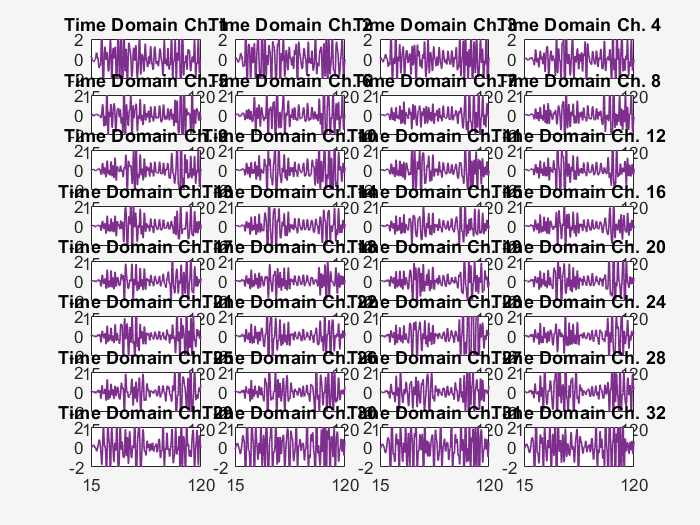


figure
for ii=1:32
    subplot(8,4,ii);
    labelArr(ii) = "Time Domain Ch. "+ (ii);
    plot(Bt, filter(lb3.lb3, unwrap(Bpha(:,ii))), 'k','LineWidth',1, 'Color', '#7E2F8E');
    title(labelArr{ii});
    axis([15, 120, -2, 2]);
    hold on
    grid on
    set(gca,'FontSize',10,'Color','w');
    set(gca, 'Xtick', [15, 120]);
end

sgtitle(['Phase of CSI vs. Time (s) for Trial: ', name_str], 'Interpreter', 'None')
fig = get(groot,'CurrentFigure');
fig.PaperPositionMode = 'auto';
fig.Color = [245, 245, 245]/255;

## Plot Frequency Domain for Channels 1 to 32

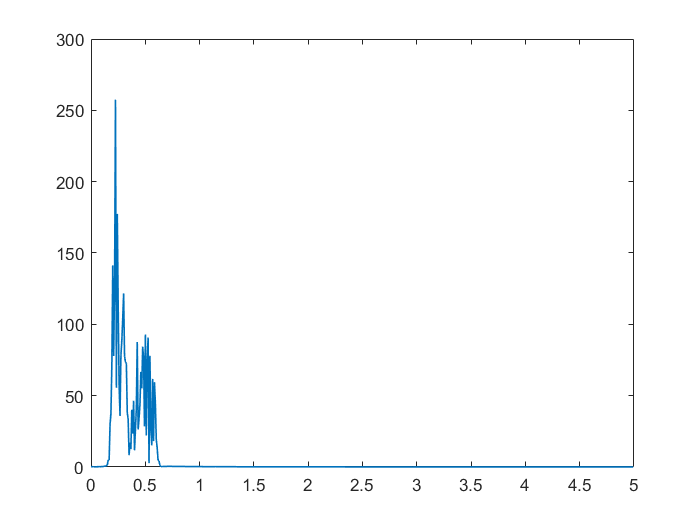

 Nsamps = length(Bpha(:,1)); %changed bsci to bpha
    Nhalf = Nsamps/2;
    fs = 10;
    f = fs*(0:Nsamps/2-1)/Nsamps;
yFreq15=abs(fft(filter(lb3.lb3, unwrap(Bpha(:,15)))));    
figure
plot(f, yFreq15(1:Nsamps/2), 'LineWidth', 1, 'Color', '#0072BD');

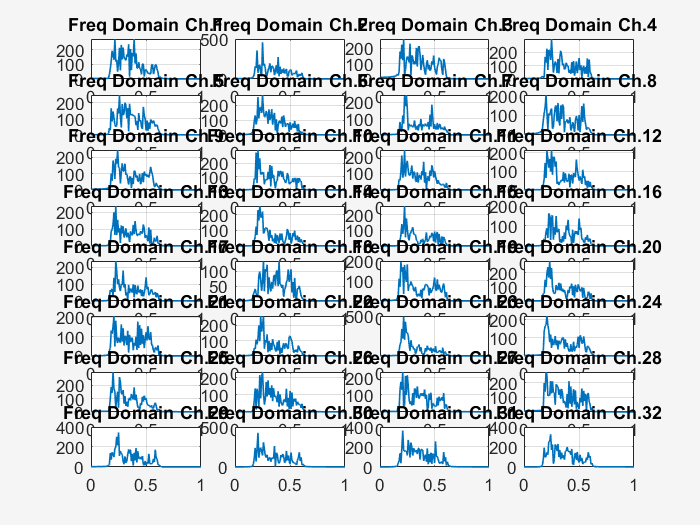

 
figure    
for jj=1:32
        
    yfreq = abs(fft(filter(lb3.lb3, unwrap(Bpha(:,jj)))));
    subplot(8,4,jj);
    
    labelFreq(jj) = "Freq Domain Ch."+ jj;
    plot(f, yfreq(1:Nsamps/2), 'LineWidth', 1, 'Color', '#0072BD');
    xlim([0, 1]);
   
    title(labelFreq{jj});

    set(gca,'FontSize',10,'Color','w');
   

    hold on
    grid on
    

end
fig = get(groot,'CurrentFigure');

fig.Color = [245, 245, 245]/255;

## Algorithm that Extracts Breathing Frequency

breathFreq = zeros(1,3);




for kk=16:18 % iterates through the 3 channels with minimal noise
          
    
    yfreq1 = abs(fft(filter(lb3.lb3,unwrap(Bpha(:,kk))))); % converts filtered signal to frequency domain 

    [pks, loc] = findpeaks(yfreq1(1:Nsamps/2), f,"MinPeakProminence", 0.05 ); % finds peaks in frequency
    [M1, I1] = max(pks);
    
    if ~isempty(loc)
        breathFreq(1,kk-15) = loc(I1);
    end   
   
       
end

if (breathFreq(1)~=breathFreq(2))&&(breathFreq(1)~=breathFreq(3))&&(breathFreq(2)~=breathFreq(3))
    M = median(breathFreq);
else 
    M = mode(breathFreq); % mode of the frequencies from the 3 channels
end
